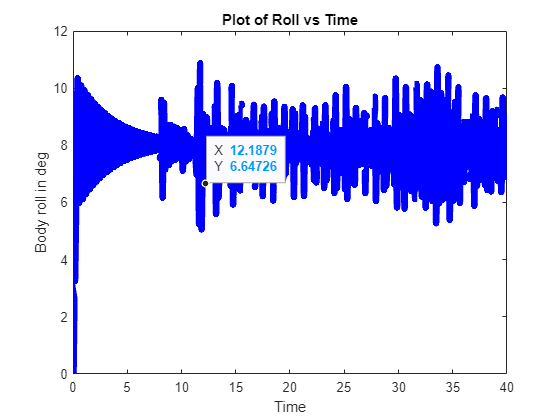

clear; % clears all var
clc; % clears command window
data = load("ph_gs_front_motor_angle.mat");
% acceleration = load("acc_y_roll_deg.mat");
% f = load("flap_angle.mat");
time = transpose(data.txyzangle(1,:));
bod_pitch = transpose(data.txyzangle(3,:));
bod_roll = transpose(data.txyzangle(4,:));
bod_roll = abs(bod_roll);
smoothed_bod_roll = smoothdata(bod_roll,'gaussian',1000);







plot(time,smoothedbod_roll,'Color','b','linewidth',5)
xlabel('Time')
ylabel('Body roll in deg')
title('Plot of Roll vs Time')

%%%%% generate motor plot %%%%%%%%%%
conversion2rads = 0.10471975513824;
convert2Newton = 9.81/1000; 
speed = conversion2rads.*[-34930 -33467 -32100 -30655 -29306 -27893 -26435 -24943 -23394 -21657 -19940 0 19940 21657 23394 24943 26435 27893 29306 30655 32100 33467 34930];
speed = transpose(speed);
thrust = convert2Newton.*[-390.47,-355.99,-324.42,-298.03,-271.05,-244.27,-219.75,-195.85,-171.90,-146.82,-122.98, 0, 122.98, 146.82, 171.90, 195.85, 219.75, 244.27, 271.05, 298.03, 324.42, 355.99, 390.47];
thrust = transpose(thrust);
f = fit(speed,thrust,'poly3'); % speed thrust function

disp (f);

     Linear model Poly3:
     f(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients (with 95% confidence bounds):
       p1 =   4.975e-11  (4.814e-11, 5.136e-11)
       p2 =   3.747e-23  (-3.852e-09, 3.852e-09)
       p3 =   0.0003889  (0.0003729, 0.0004049)
       p4 =  -3.142e-16  (-0.03431, 0.03431)


disp (f(-10));

   -0.0039



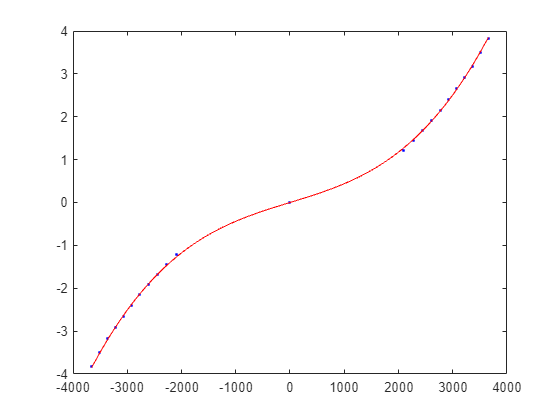

plot(f,speed,thrust);

xlabel('RPS')
ylabel('Force (N)')
title('Motor plot force vs speed')

%%%%% generate motor torque %%%%%%%%%%
% speed = [19940 21657 23394 24943 26435 27893 29306 30655 32100 33467 34930];
% speed = transpose(speed);
% power = [35.85 43.59 51.97 60.85 69.43 78.67 89.21 100.57 113.10 128.12 144.55];
% % power = transpose(power);
% torque = mrdivide(power,speed);
% % torque = transpose(torque);
% disp(torque);


clear; % clears all var
clc; % clears command window
five = load("temp_5_deg.mat");
acceleration = load("acc_y_roll_deg.mat");
f = load("flap_angle.mat");
roll_5 = transpose(five.xyz(3,:));
roll_time = transpose(five.xyz(1,:));
roll_5 = abs(roll_5);
time = 30;
disp (size(roll_5));
a = size(roll_5);
rows = round(a(1,1)/6);
disp (rows);


angles_5 = zeros(1,6);

for i = 0 : (time/6)
     
    if i == 0

        array = roll_5(round(rows/2):(rows*i)+rows,:);
        angles_5(:,i+1) = peak2peak(array);
    
    elseif i == time/6

        array = roll_5((rows*i):a(1,1),:);
        angles_5(:,i+1) = peak2peak(array);
        
    else
        
        array = roll_5(rows*i:(rows*i)+rows,:);
        angles_5(:,i+1) = peak2peak(array);

    end

end

disp(angles_5);

plot(roll_time,roll_5,'Color','b')
xlabel('Time')
ylabel('Roll angle')
title('Plot of Roll vs Time')



smoothed_data = smoothdata(roll_5,'gaussian',1000);
plot(roll_time,smoothed_data,'Color','r')
xlabel('Time(s)')
ylabel('Smoothed roll angle(deg)')
title('Plot of Smoothed roll vs Time')
grid on

flap_angle = abs(transpose(f.flap(2,:)));
flap_time = transpose(f.flap(1,:));
hold on

smoothed_data_flap = smoothdata(flap_angle,'gaussian',1000);
plot(flap_time,smoothed_data_flap,'Color','b')

legend('roll angle','flap angle')
hold off

acc = transpose(acceleration.acc_y(2,:));
%acc = abs(acc);
acc_time = transpose(acceleration.acc_y(1,:));
smoothed_data_acc = smoothdata(acc,'gaussian',1000);
plot(roll_time,smoothed_data_acc,'Color','k')
xlabel('Time(s)')
ylabel('Acceleration (m/s2)')
title('Plot of Acceleration vs Time')
grid on

% twenty = load ("20_deg.mat");
% roll_20 = transpose(twenty.attitude_wo_torque(2,:));
% 
% angles_20 = zeros(1,4);
% 
% for i = 1 : (time/6)-1
% 
%     array = roll_20(5341*i:(5341*i)+5341,:);
%     angles_20(:,i) = peak2peak(array);
% 
% end
% 
% disp(angles_20);